## Our first Quantum Circuits!

Let's create some quantum circuits exploiting MATLAB Support Package for Quantum Computing.

### A very simple circuit

This is the first, very simple circuit we want to create:

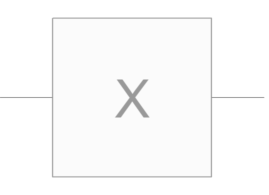

We are going to use only 1 qubit. We apply an X gate and then we want to measure our qubit.

We use **quantumCircuit**, which has the following constructor:

% qc = quantumCircuit(gates, numQubits, options)
% An example of option is "Name", which gives the quantum circuit an
% identifier

where gates is a list of gates, and numQubits is the number of qubits required by the circuit.

numQubits = 1

numQubits = 1

To apply gates, we number all qubits from 1, and create an object for every gate:

let's apply an X gate to the first qubit:

x_gate = xGate(1)

x_gate =   SimpleGate with properties:

             Type: "x"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


Let's see what kind of circuit we get up to this point:

gates = [x_gate]

gates =   SimpleGate with properties:

             Type: "x"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


qc = quantumCircuit(gates, numQubits, Name = "FirstCircuit")

qc =   quantumCircuit with properties:

    NumQubits: 1
        Gates: [1×1 quantum.gate.SimpleGate]
         Name: "FirstCircuit"


We plot the circuit:

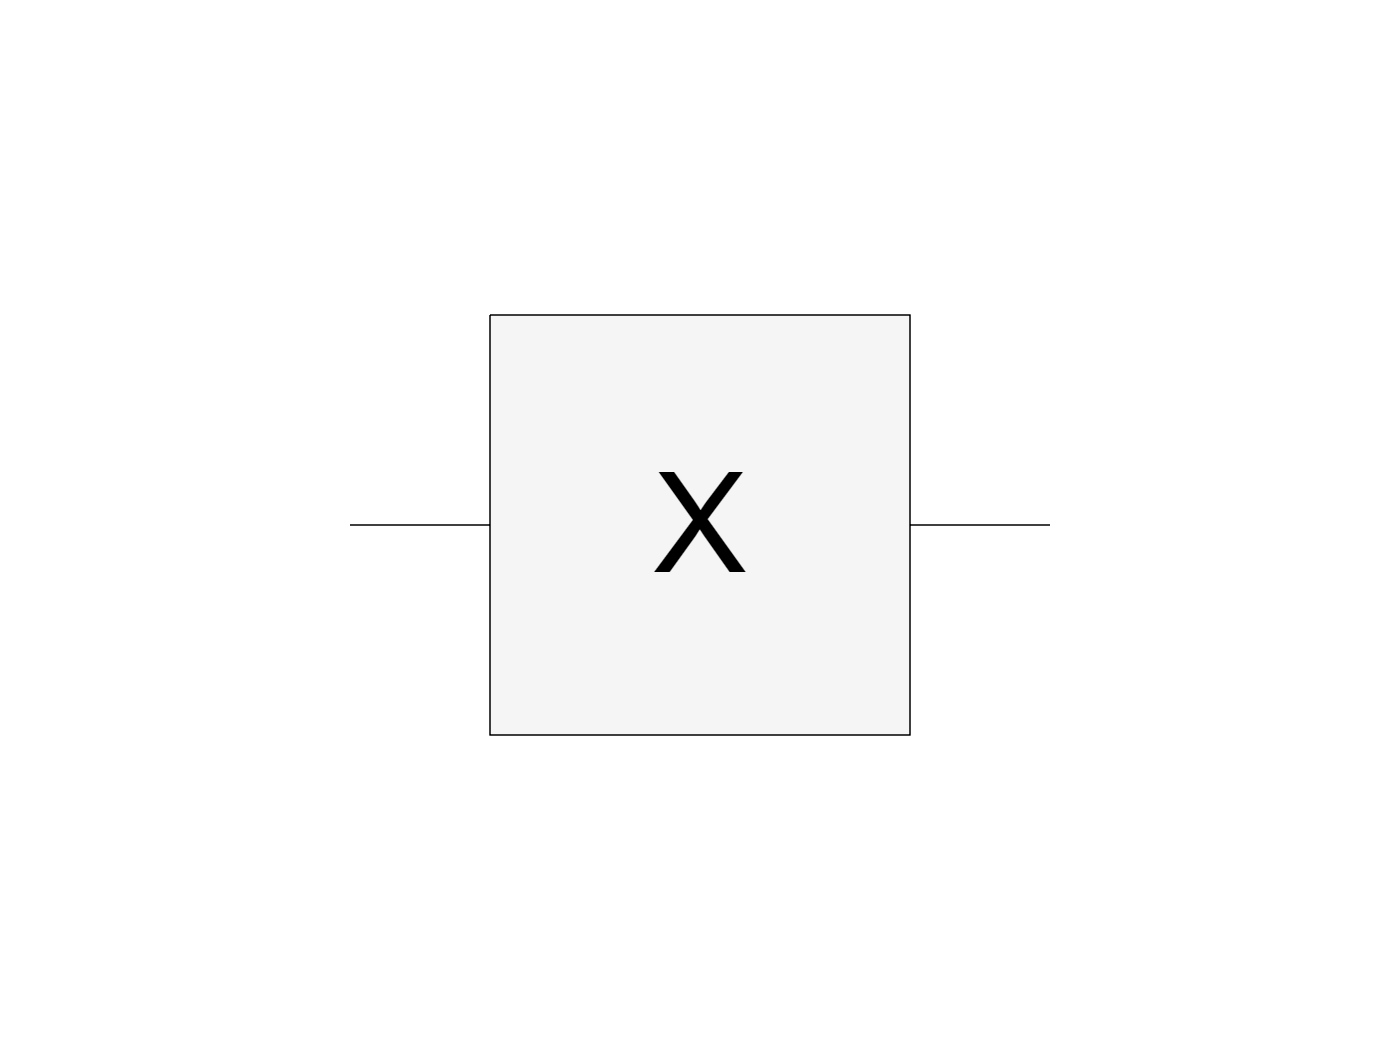

qc.plot()

Let's now simulate our circuit:

% simulate(quantumCircuit, inputState)
% inputState = we can specify how the qubits are initialized
% by default, we initialize as |0>
S = simulate(qc, "0")

S =   QuantumState with properties:

    BasisStates: [2×1 string]
     Amplitudes: [2×1 double]
      NumQubits: 1


We can now get information about the simulation and its output:

S.BasisStates

ans = 2×1 string array
    "0"
    "1"


will show the basis for the given qubits (just 1 in our case), while:

S.Amplitudes

ans =      0
     1


will display the amplitudes for each basis state, i.e., the overall state vector produced as output by the circuit.

We can also show such a state as a mathematical expression using Dirac bra-ket notation:

f = formula(S, basis = "Z") % the expression uses the computational basis {|0>, |1>}

f = "1 * |1>"

and we can even transform such a formula into another reference basis:

f2 = formula(S, basis="X") % we are now using the Hadamard basis {|+>, |->}

f2 =     "0.70711  * |+> +
     -0.70711 * |->"


Finally, we can plot a histogram showing the possible measurements and their probabilities (squared amplitudes):

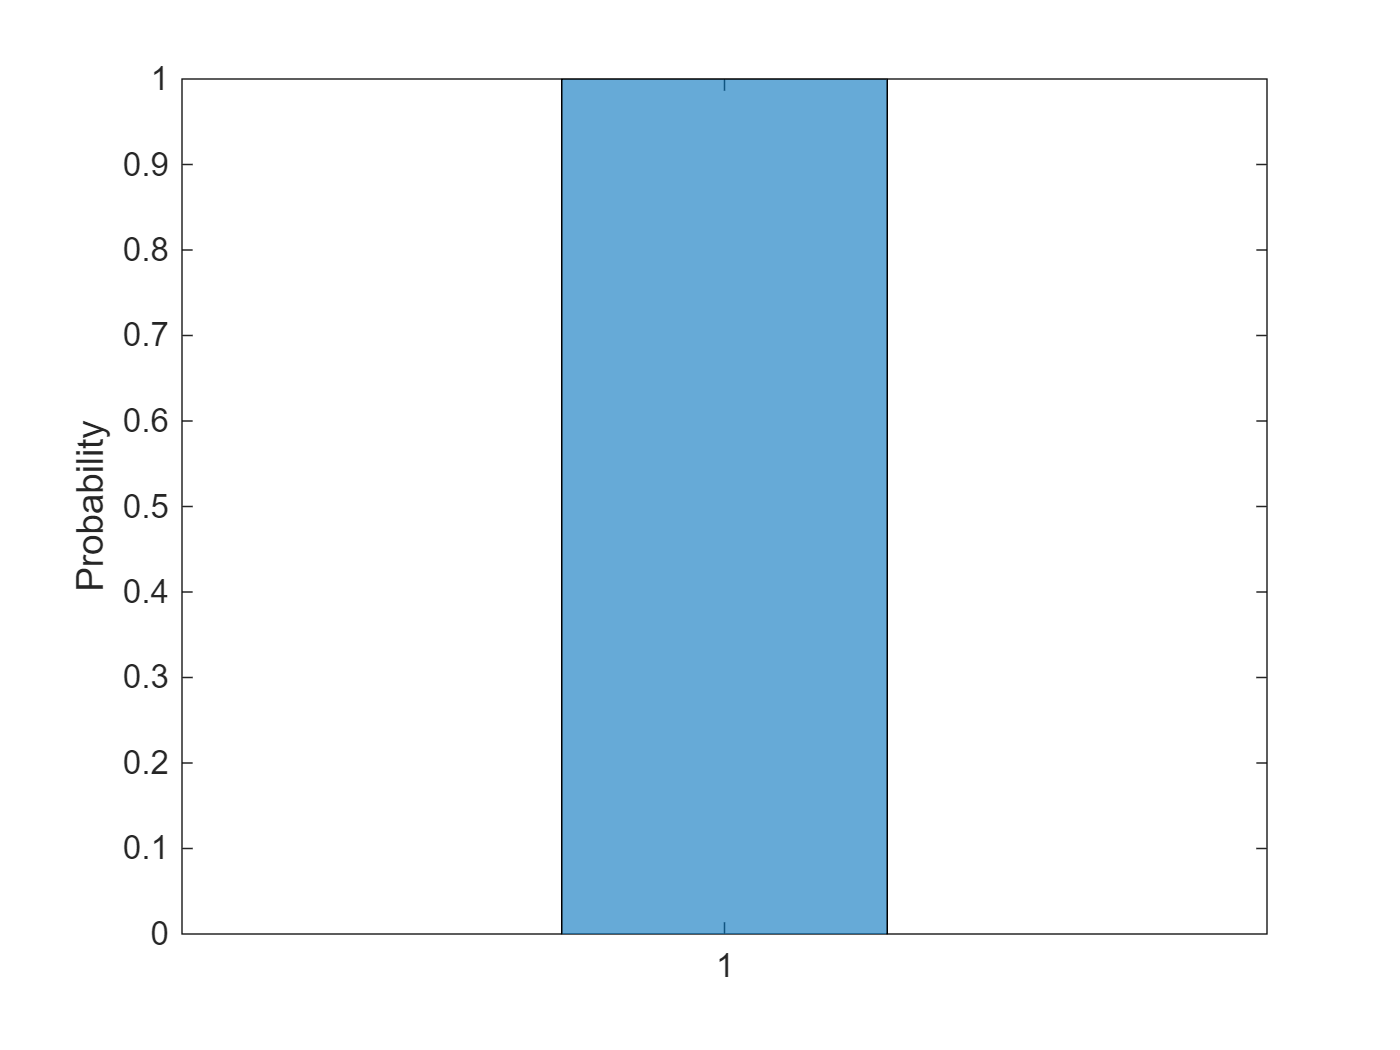

histogram(S)

As we can see, we only measure |1>! This makes sense, since we made a deterministic modification to qubit |0>. No superposition at this time!

As a final point, we can use the querystate utility to see the histogram data in a more compact, textual shape:

[states,P] = querystates(S)

states = "1"

P = 1

We can also query the probability for a specific qubit to give a specific value as output of a measurement. For example, the probability of our first qubit to be measured and give 1 as output is:

p = probability(S, 1, "1")

p = 1

Randomic simulation: measurements are probabilistic, and the simulation tells us what the final state of the qubit is. Let's now imagine that we measure our qubit 50 times: what happens? 

We can simulate our measurement process:

M = randsample(S, 50)

M =   QuantumMeasurement with properties:

    MeasuredStates: "1"
            Counts: 50
     Probabilities: 1
         NumQubits: 1


Let's display how many 0s and 1s we got:

T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 1×3 table
    Counts    Probabilities    States
    ______    _____________    ______

      50            1           "1"  


### Let's run it on a real quantum computer!

To run this code, we assume you created an IBM Quantum account and you can access its API Token.

Let's encode your authentication options in a JSON file:

myChannel = "ibm_quantum";
myInstance = "ibm-q/open/main";
%myToken = <token>; %replace with your token string 
myFileName = "ibm_quantum_auth.json";
myAccountName = "NameSurname"

myAccountName = "NameSurname"

%myCredentials = struct("channel", myChannel, "instance", myInstance, "token", myToken);
%text = jsonencode(struct(myAccountName, myCredentials), PrettyPrint=true);
%writelines(text, myFileName);

Now, we can access a quantum computer!

Let's try with IBM OSAKA (127 qubits)...

%device = quantum.backend.QuantumDeviceIBM("ibm_osaka", AccountName=myAccountName, FileName=myFileName);
%details = fetchDetails(device)

This last structure contains important information regarding your selected QPU. In particular:

- Status describes whether the QPU is active, and how many pending jobs are there before yours.

- Configuration provides you with technical details related to your QPU, such as: backend name and version, basis gates, number of instructions per second, coupling graph (in a spreadsheet version), available credits, Hamiltonian of the QPU, such as:

$\mathcal{H}/\hbar = \sum_{i=0}^{126}\left(\frac{\omega_{q,i}}{2}({I}-\sigma_i^{z})+\frac{\Delta_{i}}{2}(O_i^2-O_i)+\Omega_{d,i}D_i(t)\sigma_i^{X}\right) $ + ...

(notice: this is a contraction. The full equation shows you the energy of the WHOLE QPU, which implies a way longer equation...)

- Properties contains more info about available qubits and gates, including error rates

- Defaults contains even more details from the physical implementation of the QPU, e.g.: applied pulses and their details.

We can now run our circuit on the QPU:

%task = run(qc, device, OptimizationLevel=3)

Due to the long waiting, we manage this action as a "task". In this way, we can retrieve a print with the current status of the task, e.g., "queued" or "running":

%wait(task)

Once the task is finished, we can retrieve its output:

%R = fetchOutput(task)

R will contain info regarding the measured states, the counts, the probabilities, and the number of qubits.

We can also plot this in a tabular format:

%T = table(R.Probabilities,R.MeasuredStates, ...
%      VariableNames=["Probabilities","States"])

We can also see the formula in both bases:

%f = formula(S, basis = "Z")
%f2 = formula(S, basis="X")

And we can also plot the histogram:

%histogram(S)

As you can see, we now correctly have a perfect superposition of the two basis states. Let's simulate some random sampling:

%M = randsample(S, 50)
%T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
%    VariableNames=["Counts","Probabilities","States"])

### Let's make a superposition!

We can now test what happens if an Hadamard gate is applied to |0>:

numQubits = 1

numQubits = 1

h_gate = hGate(1)

h_gate =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


gates = [h_gate]

gates =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


qc = quantumCircuit(gates, numQubits)

qc =   quantumCircuit with properties:

    NumQubits: 1
        Gates: [1×1 quantum.gate.SimpleGate]
         Name: ""


Let's simulate and print the final basis states and amplitudes:

S = simulate(qc)

S =   QuantumState with properties:

    BasisStates: [2×1 string]
     Amplitudes: [2×1 double]
      NumQubits: 1


We can also show such a state as a mathematical expression using Dirac bra-ket notation:

f = formula(S, basis = "Z") % the expression uses the computational basis {|0>, |1>}

f =     "0.70711 * |0> +
     0.70711 * |1>"


and we can even transform such a formula into another reference basis:

f2 = formula(S, basis="X") % we are now using the Hadamard basis {|+>, |->}

f2 = "1 * |+>"

Let's see the final basis states and amplitudes:

T = table(S.BasisStates, S.Amplitudes, ...
    VariableNames=["Basis States","Amplitudes"])

T = 2×2 table
    Basis States    Amplitudes
    ____________    __________

        "0"          0.70711  
        "1"          0.70711  


Randomic simulation: measurements are probabilistic, and the simulation tells us what the final state of the qubit is. Let's now imagine that we measure our qubit 50 times: what happens? 

We can simulate our measurement process:

M = randsample(S, 50)

M =   QuantumMeasurement with properties:

    MeasuredStates: [2×1 string]
            Counts: [2×1 double]
     Probabilities: [2×1 double]
         NumQubits: 1


Let's display how many 0s and 1s we got:

T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 2×3 table
    Counts    Probabilities    States
    ______    _____________    ______

      21          0.42          "0"  
      29          0.58          "1"  


### Let's add another qubit!

We are now going to implement the following circuit:

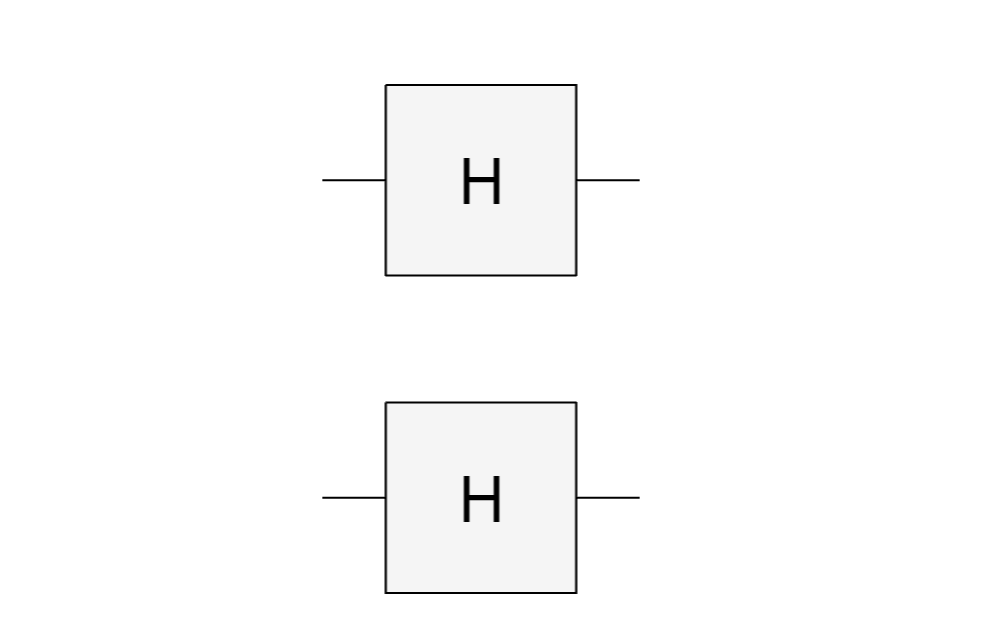

We are now going to use 2 qubits:

numQubits = 2

numQubits = 2

Let's define the gates:

hadamard_1 = hGate(1)

hadamard_1 =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


hadamard_2 = hGate(2)

hadamard_2 =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 2
           Angles: [1×0 double]


gates = [hadamard_1, hadamard_2]

gates =   1×2 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                1     
       2    h                2     


Now, we create the quantum circuit:

qc = quantumCircuit(gates, numQubits)

qc =   quantumCircuit with properties:

    NumQubits: 2
        Gates: [2×1 quantum.gate.SimpleGate]
         Name: ""


Let's see the plot:

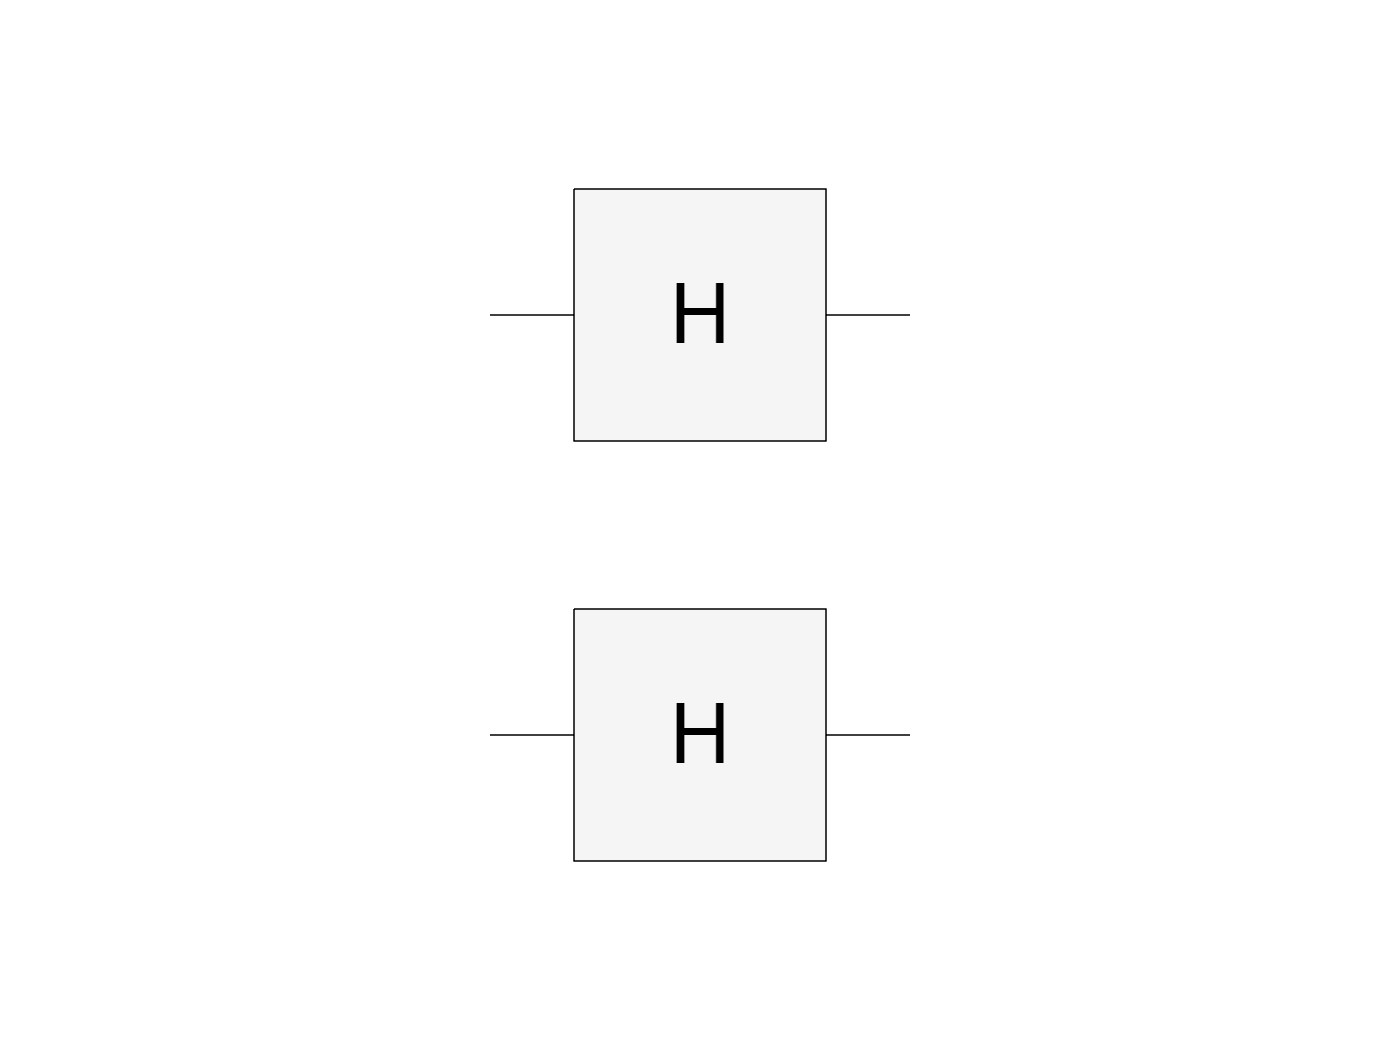

qc.plot()

We are ready to simulate, initializing all qubits to 0:

S = simulate(qc, "00")

S =   QuantumState with properties:

    BasisStates: [4×1 string]
     Amplitudes: [4×1 double]
      NumQubits: 2


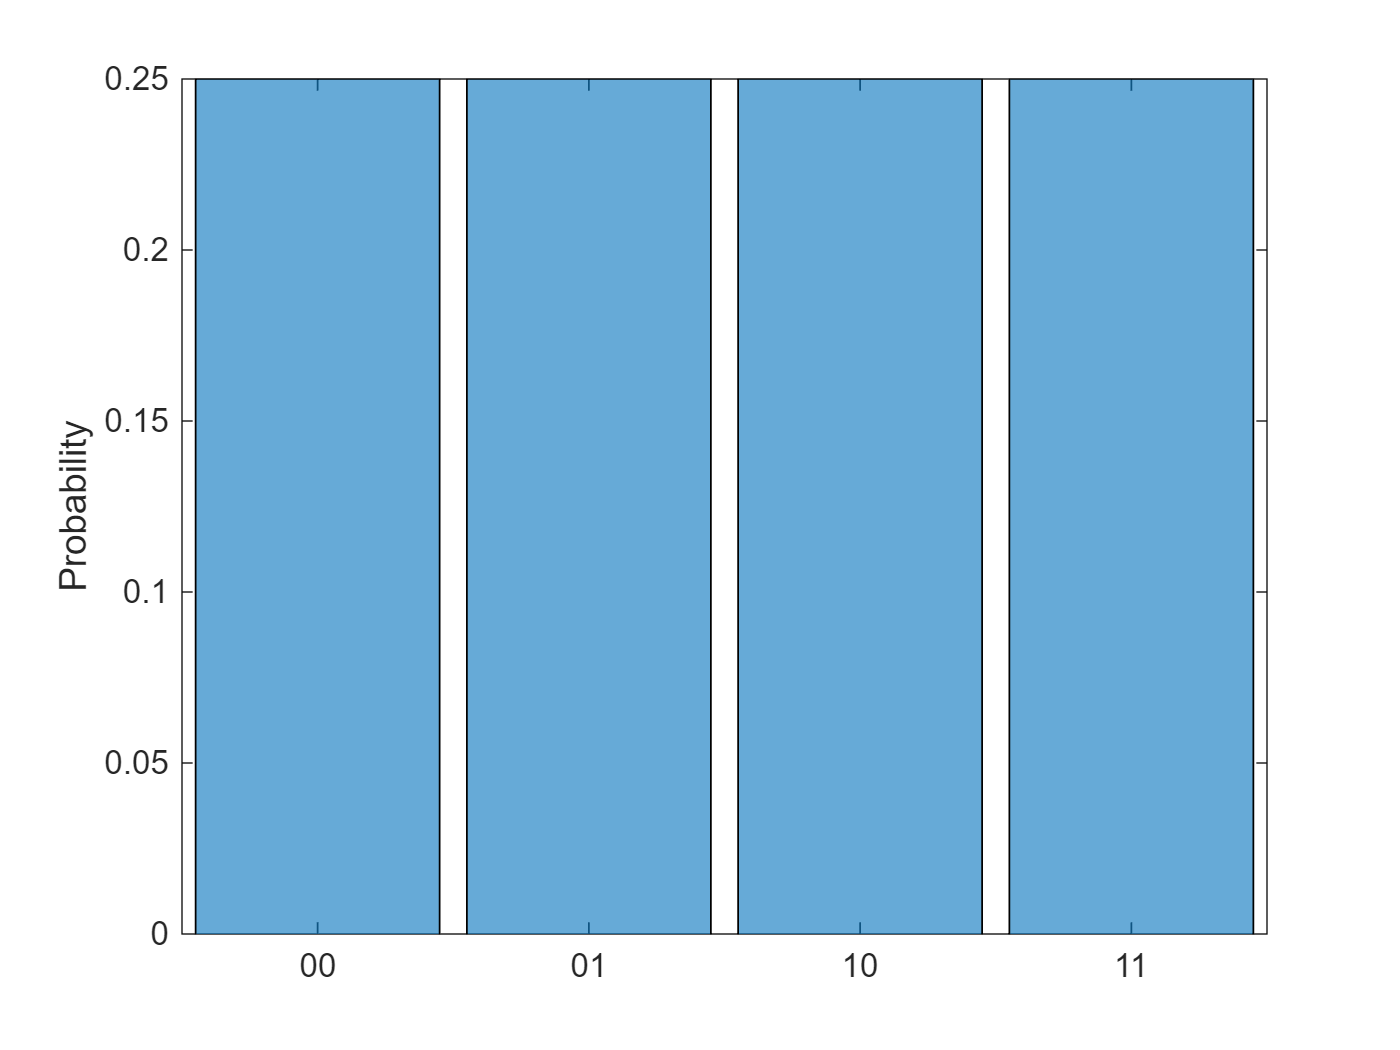

histogram(S)

We can see that now 4 basis states appear, as expected. They have all the same measurement probability.

This is also expected, as Hadamard gates, if applied to all qubits, create a perfect superposition of all the basis states.

The algebraic formula corresponding to this state is:

f1 = formula(S, Basis="Z") % computational basis

f1 =     "0.5 * |00> +
     0.5 * |01> +
     0.5 * |10> +
     0.5 * |11>"


f2 = formula(S, Basis="X") % polar basis

f2 = "1 * |++>"

Let's do some random experiments! We should approach a 25% probability for every possible measurement:

M = randsample(S, 1000)

M =   QuantumMeasurement with properties:

    MeasuredStates: [4×1 string]
            Counts: [4×1 double]
     Probabilities: [4×1 double]
         NumQubits: 2


T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 4×3 table
    Counts    Probabilities    States
    ______    _____________    ______

     255          0.255         "00" 
     241          0.241         "01" 
     279          0.279         "10" 
     225          0.225         "11" 


### Let's make an entanglement!

We want to create the following 2-qubit circuit:

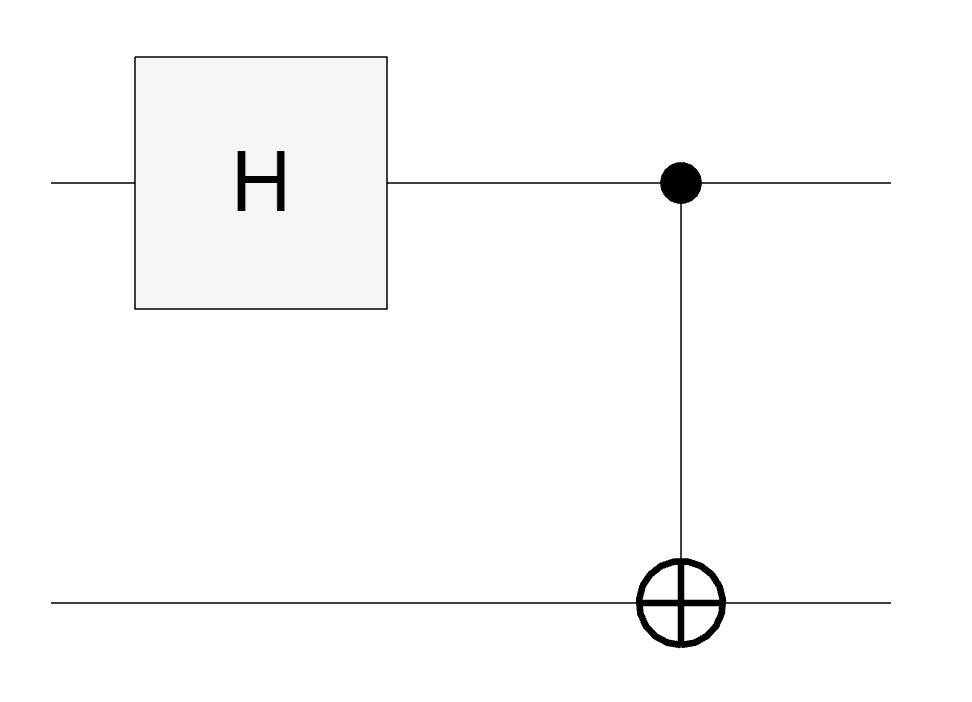

We are going to use 2 qubits. We apply a Hadamard gate to the first qubit, a controlled X (CNOT) gate using the first qubit as *control* qubit and the second one as *target* qubit, and an X gate to the first qubit.

We use **quantumCircuit**, which has the following constructor:

% qc = quantumCircuit(gates, numQubits, options)
% An example of option is "Name", which gives the quantum circuit an
% identifier

where gates is a list of gates, and numQubits is the number of qubits required by the circuit.

numQubits = 2

numQubits = 2

To apply gates, we number all qubits from 1, and create an object for every gate:

let's apply a Hadamard gate to the first qubit:

hadamard = hGate(1)

hadamard =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


let's apply a controled X (CNOT) gate, using 1 as control qubit and 2 as target qubit:

% cxGate(controlQubit, targetQubit)
cnot = cxGate(1,2)

cnot =   SimpleGate with properties:

             Type: "cx"
    ControlQubits: 1
     TargetQubits: 2
           Angles: [1×0 double]


Let's see what kind of circuit we get up to this point:

gates = [hadamard, cnot]

gates =   1×2 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                1     
       2    cx     1         2     


qc = quantumCircuit(gates, numQubits)

qc =   quantumCircuit with properties:

    NumQubits: 2
        Gates: [2×1 quantum.gate.SimpleGate]
         Name: ""


We plot the circuit:

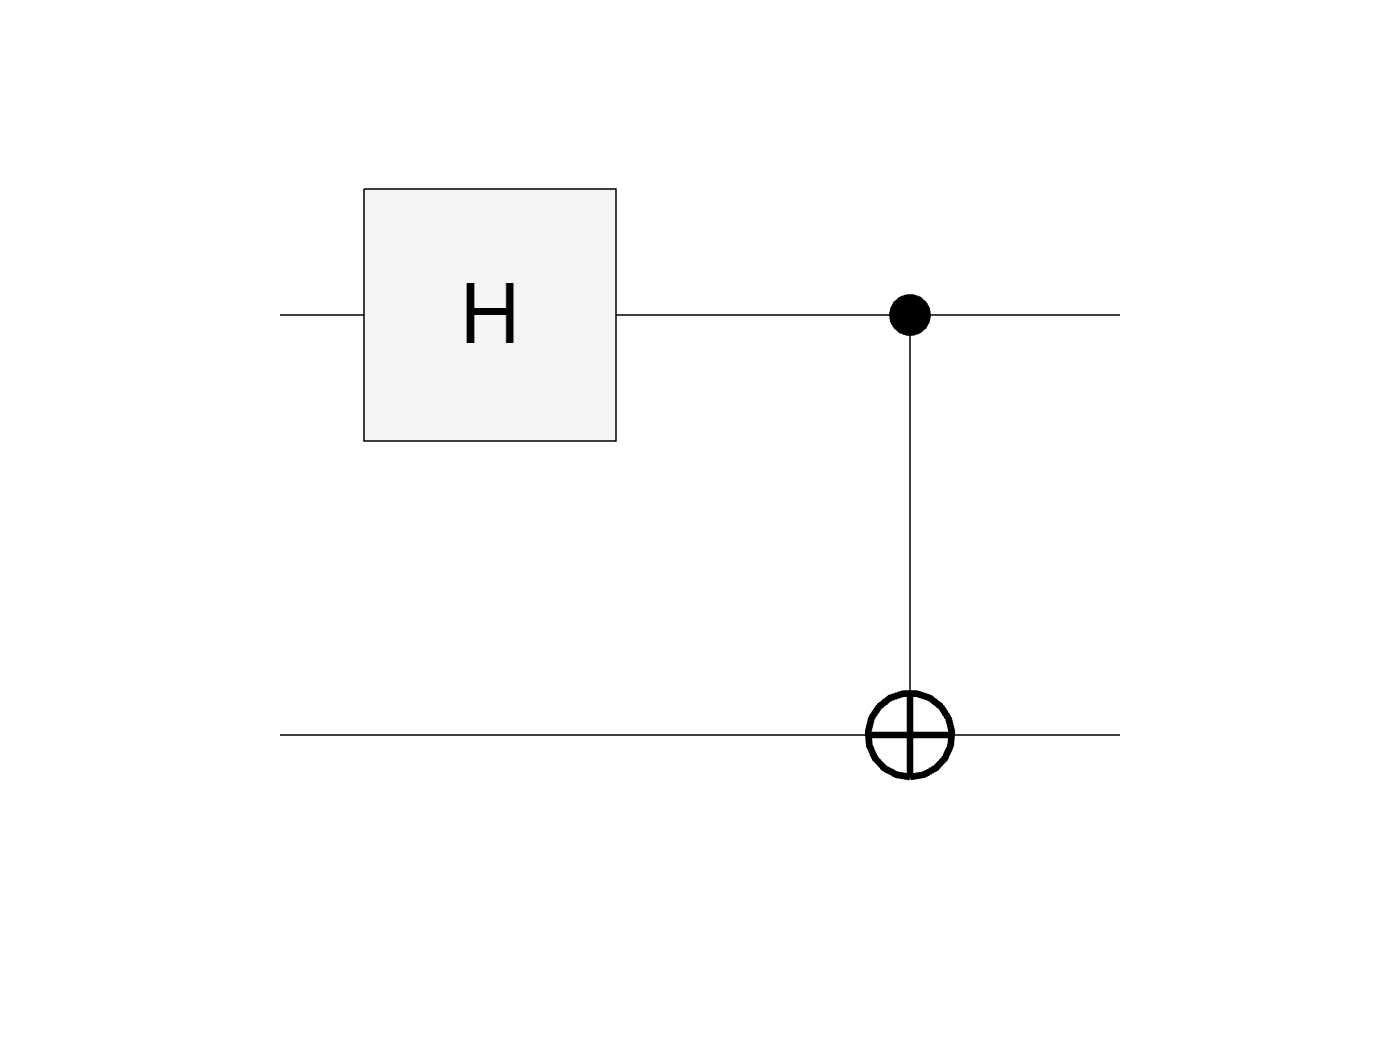

qc.plot()

This is **ENTANGLEMENT**! Let's simulate it:

S = simulate(qc, "00")

S =   QuantumState with properties:

    BasisStates: [4×1 string]
     Amplitudes: [4×1 double]
      NumQubits: 2


We can also show such a state as a mathematical expression using Dirac bra-ket notation:

f = formula(S, basis = "Z") % the expression uses the computational basis {|0>, |1>}

f =     "0.70711 * |00> +
     0.70711 * |11>"


and we can even transform such a formula into another reference basis:

f2 = formula(S, basis="X") % we are now using the Hadamard basis {|+>, |->}

f2 =     "0.70711 * |++> +
     0.70711 * |-->"


Let's see the final basis states and amplitudes:

T = table(S.BasisStates, S.Amplitudes, ...
    VariableNames=["Basis States","Amplitudes"])

T = 4×2 table
    Basis States    Amplitudes
    ____________    __________

        "00"         0.70711  
        "01"               0  
        "10"               0  
        "11"         0.70711  


Let's also plot the corresponding histogram:

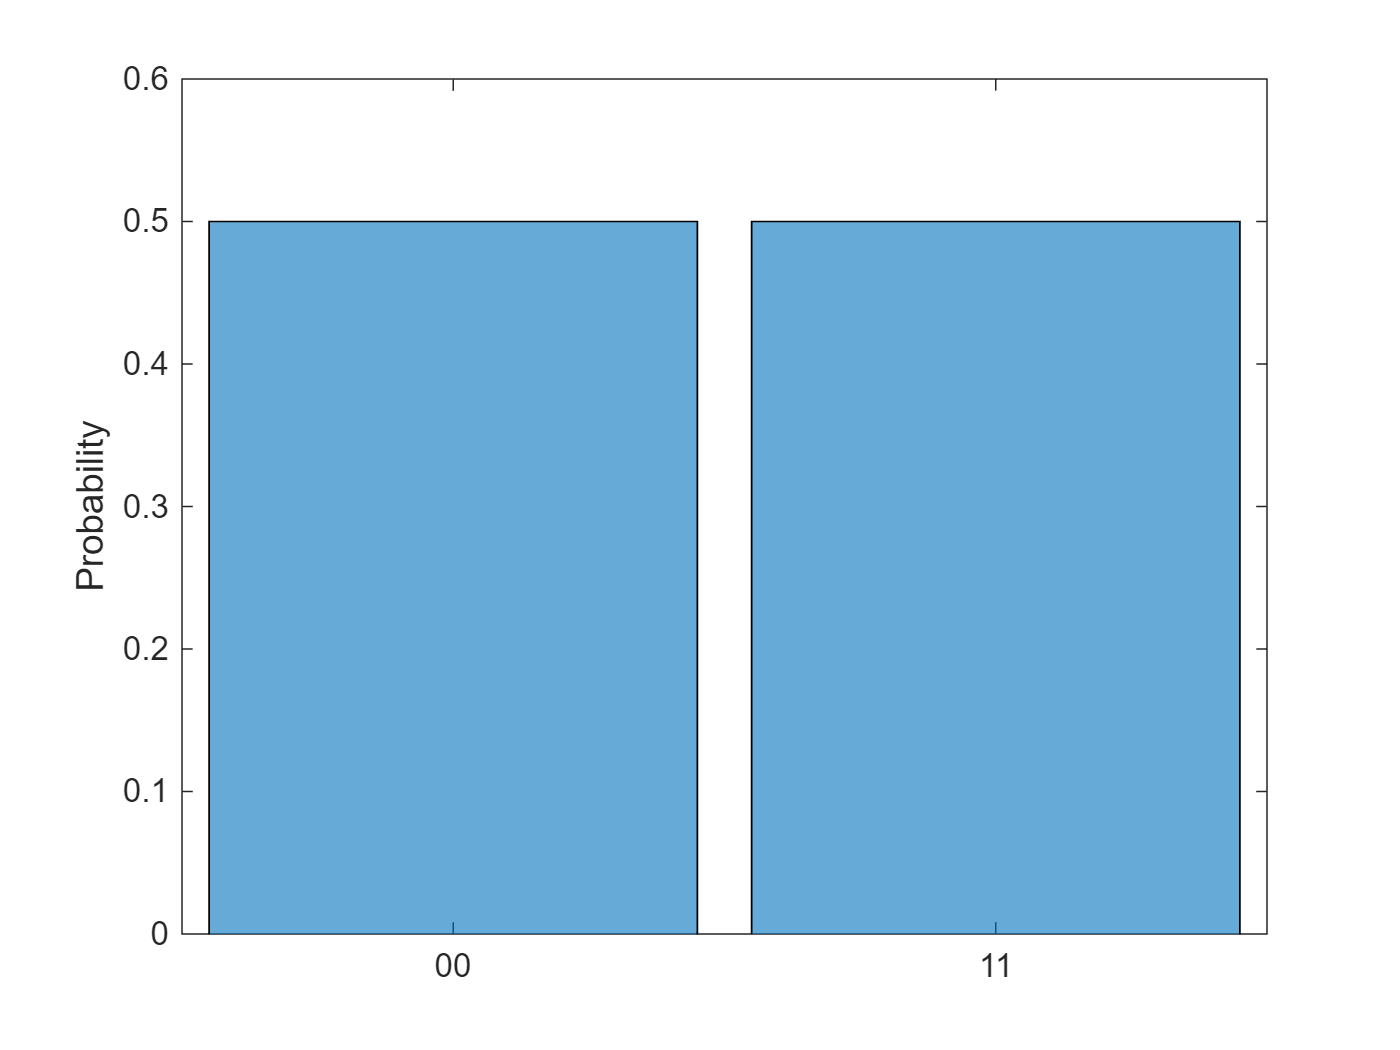

histogram(S)

M = randsample(S, 1000)

M =   QuantumMeasurement with properties:

    MeasuredStates: [2×1 string]
            Counts: [2×1 double]
     Probabilities: [2×1 double]
         NumQubits: 2


T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 2×3 table
    Counts    Probabilities    States
    ______    _____________    ______

     484          0.484         "00" 
     516          0.516         "11" 


As you can notice, differently from the previous circuit, now only two basis states can be measured. This is a result of the entanglement: after measuring the first qubit, we can deterministically know the output of the measurement for the second qubit. If the first qubit is measured as 0, the second will be 0 as well, without needing to measure.